ME599 Midterm

Aaron Cornelius

2020-10-13

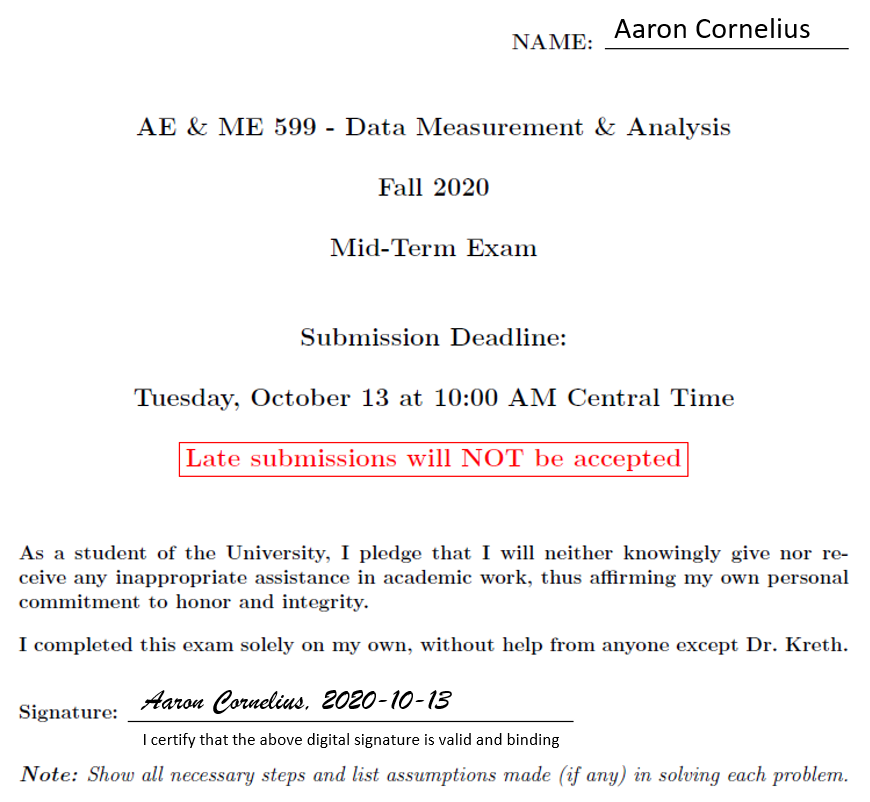

Matlab code for the relevant problems is included alongside the other material.

warning('off')

## Problem 1 (30 points)

### Part 1

A dynamic system is provided sinusoidal excitation by a sine wave input $u\left(t\right)=\mathrm{sin}\left(t\right)$. If the system is first-order with an impulse response function $h\left(t\right)=\frac{1}{\tau }e^{\frac{-t}{\tau }}$ where $\tau =2\;\left\lbrack \mathrm{s}\right\rbrack$, determine the system output $y\left(t\right)$ by evaluating the convolution integral numerically.

#### (a)

Produce a graph that shows the system output compared to the input. Ensure that you have used an appropriate discretization time step and show the solution to $t=30\;\left\lbrack \mathrm{s}\right\rbrack$.

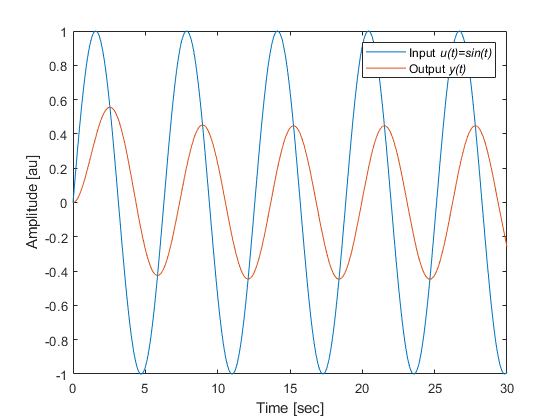

tau=2;
hFunc = @(t) 1/tau .* exp(-t/tau);
xFunc = @(t) sin(t);
yFunc = @(t) integral(@(tau) hFunc(tau).*xFunc(t-tau), 0, t);
figure
clf
fplot(xFunc, [0, 30])
hold on
fplot(yFunc, [0, 30])
legend(["Input \it{u(t)=sin(t)}" "Output \it{y(t)}"])
xlabel('Time [sec]')
ylabel('Amplitude [au]')

#### (b)

Does the output $y\left(t\right)$ have the same frequency as the input sine wave $u\left(t\right)$? If not, what is its frequency? Explain.

Since the system is linear, the output $y\left(t\right)$ must have the same frequency as the input. Linear systems can only change the magnitude and phase of the input, not the frequency. Therefore, the output frequency $f_{\mathrm{out}} =f_{\mathrm{in}} =\frac{1}{2\pi }\left\lbrack \mathrm{Hz}\right\rbrack$.

Visually, the output does appear to have the same frequency as the input wave. This can be verified analytically by integrating the product of the input function and the impulse response, where $\tau$ is the time lag, $t$ is the time, and $T$ is the time constant from the original equation (renamed to avoid overlap.)


$$y\left(t\right)=\int_0^t h\left(\tau \right)u\left(t-\tau \right)\;d\tau =\int_0^t \frac{1}{T}\mathrm{exp}\left(-\frac{\tau }{T}\right)\mathrm{sin}\left(t-\tau \right)\;d\tau$$


Using Euler's formula, $\sin \left(t-\tau \right)$ is equal to the imaginary component of $\mathrm{exp}\left(j\left(t-\tau \right)\right)$. The integration can be done by extracting the imaginary component of the integration:


$$\begin{array}{l}
\int_0^t \frac{1}{T}\mathrm{exp}\left(-\frac{\tau }{T}\right)\mathrm{sin}\left(t-\tau \right)\;d\tau +\int_0^t \frac{1}{T}\mathrm{exp}\left(-\frac{\tau }{T}\right)\mathrm{cos}\left(t-\tau \right)\;d\tau =\int_0^t \frac{1}{T}\mathrm{exp}\left(-\frac{\tau }{T}+j\;\left(t-\tau \right)\right)\;d\tau \\
=\frac{1}{T}\int_0^t \mathrm{exp}\left(-\frac{\tau }{T}+j\;t-j\;\tau \right)\;d\tau =\frac{1}{T}\int_0^t \mathrm{exp}\left(\tau \left(-\frac{1}{T}-j\right)+j\;t\right)\;d\tau \\
=\frac{1}{T}\cdot \frac{1}{\frac{1}{T}-j}\cdot \left(\mathrm{exp}\left(-\frac{t}{T}+j\;t-j\;t\right)-\mathrm{exp}\left(-\frac{0}{T}+j\;t-0j\right)\right)\\
=\frac{1}{T}\cdot \frac{\frac{1}{T}+j}{\frac{1}{T}+j}\cdot \frac{1}{\frac{1}{T}-j}\cdot \left(\mathrm{exp}\left(-\frac{t}{T}\right)-\mathrm{exp}\left(j\;t\right)\right)\\
=\frac{\frac{1}{T^2 }+\frac{j}{T}}{\frac{1}{T^2 }+1}\cdot \left(\mathrm{exp}\left(-\frac{t}{T}\right)-\mathrm{exp}\left(j\;t\right)\right)\\
=\frac{\frac{1}{T^2 }+\frac{j}{T}}{\frac{1}{T^2 }+1}\cdot \left(\mathrm{exp}\left(-\frac{t}{T}\right)-\mathrm{cos}\left(t\right)-j\;\mathrm{sin}\left(t\right)\right)
\end{array}$$


While the integration can be further simplified, at this point it's obvious that the only periodic terms are $\mathrm{cos}\left(t\right),\mathrm{sin}\left(t\right)$. The equation would need to be further simplified to extract the phase angle, but since those are the only periodic terms it is obvious that the period of the output frequency is equal to the input frequency.

#### (c)

Does the output lead or lag the input? If so, which? What is the time delay between $y$ and $u$? What is the phase offset? Justify your answers to this part analytically.

Visually, it can be seen that the output lags behind the input by approximately $1\ldotp 05\;\left\lbrack \mathrm{s}\right\rbrack$, equivelent to $1\ldotp 05\;\left\lbrack \mathrm{s}\right\rbrack \cdot 1\;\left\lbrack \frac{\mathrm{rad}}{\mathrm{s}}\right\rbrack =1\ldotp 05\;\left\lbrack \mathrm{rad}\right\rbrack$. The phase difference can be determined from the frequency response function $H\left(f\right)=\int_0^{\infty } h\left(t\right)\mathrm{exp}\left(-2j\pi ft\right)\;dt$.


$$\begin{array}{l}
H\left(f\right)=\int_0^{\infty } h\left(t\right)\mathrm{exp}\left(-2j\pi f\tau \right)\;d\tau =\int_0^{\infty } \frac{1}{\tau }e^{\frac{-t}{\tau }} \;\mathrm{exp}\left(-2j\pi ft\right)\;\mathrm{dt}\\
=\frac{1}{\tau }\int_0^{\infty } \;\mathrm{exp}\left(-\frac{t}{\tau }-2j\pi ft\right)\;\mathrm{dt}=\frac{1}{\tau }\int_0^{\infty } \;\mathrm{exp}\left(t\left(-\frac{1}{\tau }-2j\pi f\right)\right)\;\mathrm{dt}\\
=\frac{1}{\tau }\cdot \frac{1}{-2j\pi f-\frac{1}{\tau }}\cdot \left(\;\mathrm{exp}\left(\infty \left(-\frac{1}{\tau }-2j\pi f\right)\right)-\;\mathrm{exp}\left(0\left(-\frac{1}{\tau }-2j\pi f\right)\right)\right)
\end{array}$$


Since $e^{-\infty } =0,e^0 =1$, this simplifies to:


$$\begin{array}{l}
H\left(f\right)=-\frac{1}{\tau }\cdot \frac{1}{-2j\pi f-\frac{1}{\tau }}=-\frac{1}{\tau }\cdot \frac{1}{-2j\pi f-\frac{1}{\tau }}\cdot \frac{2j\pi f-\frac{1}{\tau }}{2j\pi f-\frac{1}{\tau }}=-\frac{1}{\tau }\cdot \frac{2j\pi f-\frac{1}{\tau }}{\frac{1}{\tau^2 }+4\pi^2 f^2 }=\frac{-\frac{2j\pi f}{\tau }+\frac{1}{\tau^2 }}{\frac{1}{\tau^2 }+4\pi^2 f^2 }\\
\Rightarrow H_{\mathrm{real}} \left(f\right)=\frac{\frac{1}{\tau^2 }}{\frac{1}{\tau^2 }+4\pi^2 f^2 },H_{\mathrm{imag}} \left(f\right)=\frac{-\frac{2\pi f}{\tau }}{\frac{1}{\tau^2 }+4\pi^2 f^2 }\\
\Rightarrow |H_{\mathrm{real}} \left(f\right)|=\sqrt{H_{\mathrm{real}} {\left(f\right)}^2 +H_{\mathrm{imag}} {\left(f\right)}^2 }=\sqrt{{\left(\frac{\frac{1}{\tau^2 }}{\frac{1}{\tau^2 }+4\pi^2 f^2 }\right)}^2 +{\left(\frac{\frac{2\pi f}{\tau }}{\frac{1}{\tau^2 }+4\pi^2 f^2 }\right)}^2 }\\
=\frac{\sqrt{{\left(\frac{1}{\tau^2 }\right)}^2 +{\left(\frac{2\pi f}{\tau }\right)}^2 }}{\frac{1}{\tau^2 }+4\pi^2 f^2 }=\frac{\sqrt{\frac{1}{\tau^4 }+\frac{4\pi^2 f^2 }{\tau^2 }}}{\frac{1}{\tau^2 }+4\pi^2 f^2 }\\
\angle H\left(f\right)=\mathrm{atan2}\left(H_{\mathrm{imag}} \left(f\right),H_{\mathrm{real}} \left(f\right)\right)=\mathrm{atan2}\left(\frac{-\frac{2\pi f}{\tau }}{\frac{1}{\tau^2 }+4\pi^2 f^2 },\frac{\frac{1}{\tau^2 }}{\frac{1}{\tau^2 }+4\pi^2 f^2 }\right)
\end{array}$$
 

The frequency of this function is $1\;\left\lbrack \frac{\mathrm{rad}}{s}\right\rbrack =\frac{1}{2\pi }\;\left\lbrack \mathrm{Hz}\right\rbrack$. The phase angle $\angle H\left(\frac{1}{2\pi }\right)$ can be calculated from the frequency response:


$$\angle H\left(\frac{1}{2\pi }\right)=\mathrm{atan2}\left(-\frac{2}{5},\frac{1}{5}\right)\approx -1\ldotp 1071\;\left\lbrack \mathrm{rad}\right\rbrack \approx -63\ldotp 4\;\left\lbrack °\right\rbrack$$


atan2(-0.4, 0.2)/pi*180;

The time lag $t_{\mathrm{lag}}$ can be calculated by dividing that phase lag by the input frequency:


$$t_{\mathrm{lag}} =\frac{-1\ldotp 1071\;\left\lbrack \mathrm{rad}\right\rbrack }{1\left\lbrack \frac{\mathrm{rad}}{\mathrm{s}}\right\rbrack }=-1\ldotp 1071\;\left\lbrack \mathrm{s}\right\rbrack$$


This result matches with the value that was estimated graphically.

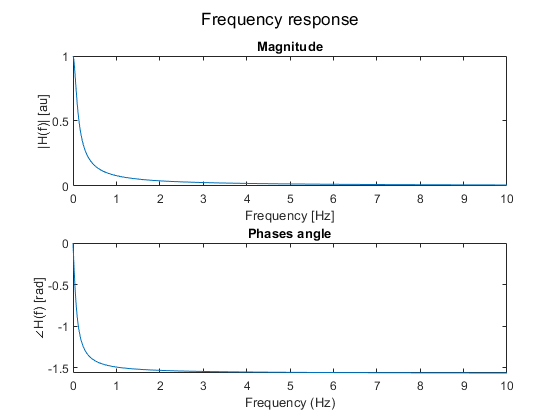

H = @(f) -(2i*pi*f/tau-1./tau.^2)./(1./(tau).^2+4*pi^2.*f.^2);
figure
clf
subplot(2,1,1)
fplot(@(f)abs(H(f)),[0 10])
sgtitle('Frequency response')
title('Magnitude')
xlabel('Frequency [Hz]')
ylabel('|H(f)| [au]')
subplot(2,1,2)
fplot(@(f)angle(H(f)),[0 10])
title('Phases angle')
xlabel('Frequency (Hz)')
ylabel('{\angle}H(f) [rad]')

#### (d)

What is the system's steady-state response? Provide your answer in an analytical form, ensuring that the amplitude, phase, etc are correctly determined.

Since the input is purely a sine wave, it is known that the output must also be a pure sine wave of the same frequency. The steady state response can be determined from the frequency response where $\omega =1\left\lbrack \frac{\mathrm{rad}}{\mathrm{s}}\right\rbrack =\frac{1}{2\pi }\left\lbrack \mathrm{Hz}\right\rbrack$. The frequency response $H\left(f\right)$ has already been established:


$$\begin{array}{l}
H\left(f\right)=\frac{-\frac{2j\pi f}{\tau }+\frac{1}{\tau^2 }}{\frac{1}{\tau^2 }+4\pi^2 f^2 }\\
\Rightarrow H\left(\frac{1}{2\pi }\right)=\frac{-\frac{2j\pi \frac{1}{2\pi }}{\tau }+\frac{1}{\tau^2 }}{\frac{1}{\tau^2 }+4\pi^2 {\left(\frac{1}{2\pi }\right)}^2 }\\
=\frac{-\frac{j}{\tau }+\frac{1}{\tau^2 }}{\frac{1}{\tau^2 }+1}\\
\Rightarrow H_{\mathrm{real}} \left(\frac{1}{2\pi }\right)=\frac{1}{1+\tau^2 },H_{\mathrm{imag}} \left(\frac{1}{2\pi }\right)=-\frac{1}{\frac{1}{\tau }+\tau }
\end{array}$$


Plugging in the value of $\tau =2$:


$$\begin{array}{l}
H_{\mathrm{real}} \left(\frac{1}{2\pi }\right)=\frac{1}{1+4}=\frac{1}{5},H_{\mathrm{imag}} \left(\frac{1}{2\pi }\right)=-\frac{1}{\frac{1}{2}+2}=-\frac{2}{5}\\
\angle H\left(f\right)=\mathrm{atan2}\left(H_{\mathrm{imag}} \left(f\right),H_{\mathrm{real}} \left(f\right)\right)\Rightarrow \angle H\left(\frac{1}{2\pi }\right)=\mathrm{atan2}\left(-\frac{2}{5},\frac{1}{5}\right)\approx -1\ldotp 1071\;\left\lbrack \mathrm{rad}\right\rbrack \approx -63\ldotp 4\;\left\lbrack °\right\rbrack \\
|H\left(f\right)|=\sqrt{H_{\mathrm{imag}} {\left(f\right)}^2 +H_{\mathrm{real}} {\left(f\right)}^2 }\Rightarrow |H\left(\frac{1}{2\pi }\right)|=\sqrt{{\left(-\frac{2}{5}\right)}^2 +{\left(\frac{1}{5}\right)}^2 }=\sqrt{\frac{5}{25}}=\sqrt{\frac{1}{5}}\approx 0\ldotp 447
\end{array}$$


Now that the Fourier response is known, this can be assembled into the time domain response:


$$\begin{array}{l}
y\left(t\right)=H_{\mathrm{real}} \left(\frac{1}{2\pi }\right)\mathrm{cos}\left(t\right)+H_{\mathrm{imag}} \left(\frac{1}{2\pi }\right)\mathrm{sin}\left(t\right)=|H\left(\frac{1}{2\pi }\right)|\mathrm{sin}\left(t-\angle H\left(\frac{1}{2\pi }\right)\right)\\
\Rightarrow y\left(t\right)\approx 0\ldotp 447\;\mathrm{sin}\left(t-1\ldotp 1071\right)
\end{array}$$


This will now be graphically compared to the total solution that was previously numericaly obtained. The steady state is initially different from the total numerical solution, but over time they converge.

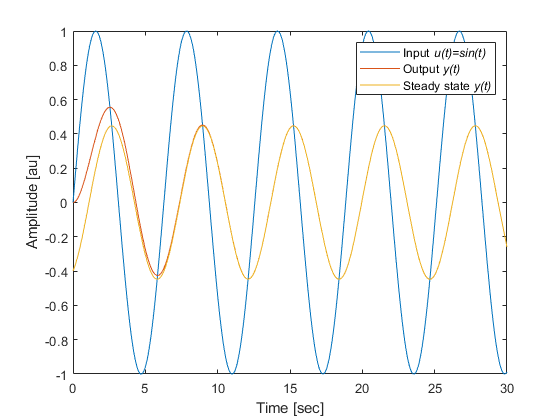

tau=2;
hFunc = @(t) 1/tau .* exp(-t/tau);
xFunc = @(t) sin(t);
yFunc = @(t) integral(@(tau) hFunc(tau).*xFunc(t-tau), 0, t);
ySteadyState = @(t) 0.447*sin(t-1.1071);
figure
clf
fplot(xFunc, [0, 30])
hold on
fplot(yFunc, [0, 30])
fplot(ySteadyState, [0, 30])
legend(["Input \it{u(t)=sin(t)}" "Output \it{y(t)}" "Steady state \it{y(t)}"])
xlabel('Time [sec]')
ylabel('Amplitude [au]')

#### (e)

How long does the system take to reach the steady state solution? Justify your answer.

Given that the transfer function is an exponential, it will never, technically reach the steady state solution, just asymptotically approach it. However, the degree to which it has approached the steady state can be determined by how much of the transfer function is being used. At some time $T$, this can be determined by integrating the transfer function from 0 to $T$ to determine what portion of the area under the transfer function is actually i use. At $T=\infty$, this will yield:


$$\int_0^{\infty } h\left(t\right)\;dt=\int_0^{\infty } \frac{1}{\tau }e^{\frac{-t}{\tau }} \;dt=\frac{-\tau }{\tau }\left(e^{-\infty } -e^0 \right)=1$$


So a value of 1 indicates that the function has fully reached the steady state. This can be solved for any arbitrary desired percentage. For example, the system has converged 99% of the way to steady state (i.e., 99% of the area under the transfer function is contributing to the output response, and only 1% of the response is due to transient effects) when:


$$\begin{array}{l}
0\ldotp 99=\int_0^T \frac{1}{\tau }e^{\frac{-t}{\tau }} \;dt=\frac{-\tau }{\tau }\left(e^{-\frac{T}{\tau }} -e^0 \right)=1-e^{-\frac{T}{\tau }} \\
\Rightarrow e^{-\frac{T}{\tau }} =0\ldotp 01\\
\Rightarrow T=-\tau \cdot \mathrm{ln}\left(0\ldotp 01\right)\approx 9\ldotp 21\left\lbrack \mathrm{s}\right\rbrack 
\end{array}$$


This matches up with visual inspection of the graph above: after ~9 seconds, the steady state and total solutions have nearly perfectly converged.

### Part 2

Repeat parts (a) through (e) with an impulse response function of:


$$h\left(t\right)=\mathrm{exp}\left(-\zeta \omega_n t\right)\;\frac{\mathrm{sin}\left(\omega_d t\right)}{\omega_d }$$


where $\omega_n =0\ldotp 5\;\left\lbrack \frac{\mathrm{rad}}{\mathrm{s}}\right\rbrack ,\zeta =\frac{1}{\sqrt{2}},\omega_d =\omega_n \sqrt{1-\zeta^2 }$

#### (a)

Produce a graph that shows the system output compared to the input. Ensure that you have used an appropriate discretization time step and show the solution to $t=30\;\left\lbrack \mathrm{s}\right\rbrack$.

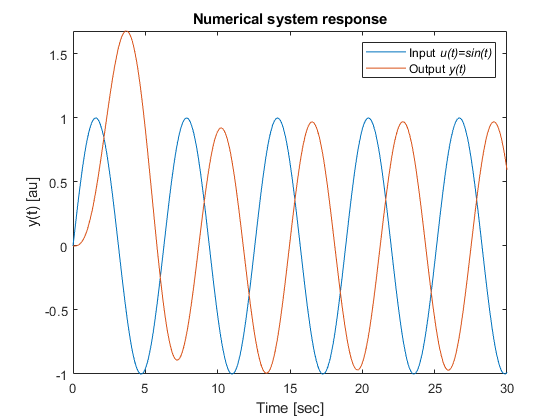

omega_n = 0.5; % Natural frequency, rad/sec
zeta = 1/sqrt(2); % Damping ratio
omega_d = omega_n*sqrt(1-zeta^2); % Damped natural frequency
hFunc = @(t) exp(-zeta*omega_n*t).*sin(omega_d*t)/omega_d;
xFunc = @(t) sin(t);
yFunc = @(t) integral(@(tau) hFunc(tau).*xFunc(t-tau), 0, t);
figure
clf
fplot(xFunc, [0, 30])
hold on
fplot(yFunc, [0, 30])
legend(["Input \it{u(t)=sin(t)}" "Output \it{y(t)}"])
xlabel('Time [sec]')
ylabel('y(t) [au]')
title('Numerical system response')

#### (b)

Does the output $y\left(t\right)$ have the same frequency as the input sine wave $u\left(t\right)$? If not, what is its frequency? Explain.

Since the system is linear, the output $y\left(t\right)$ must have the same frequency as the input. Linear systems can only change the magnitude and phase of the input, not the frequency. Therefore, the output frequency $f_{\mathrm{out}} =f_{\mathrm{in}} =1\left\lbrack \frac{\mathrm{rad}}{\mathrm{sec}}\right\rbrack =\frac{1}{2\pi }\left\lbrack \mathrm{Hz}\right\rbrack$.

#### (c)

Does the output lead or lag the input? If so, which? What is the time delay between $y$ and $u$? What is the phase offset? Justify your answers to this part analytically.

Visually, it can be seen that the output lags the input by approximately 2.35 seconds.

As before, this can be found from the Fourier transform, using the imaginary portion of the Euler equivelent of the sine function in $h\left(t\right)$:


$$\begin{array}{l}
h\left(t\right)=\mathrm{exp}\left(-\zeta \omega_n t\right)\;\frac{\mathrm{sin}\left(\omega_d t\right)}{\omega_d }\\
\frac{1}{\omega_d }\mathrm{exp}\left(-\zeta \omega_n t\right)\;\left(\mathrm{cos}\left(\omega_d t\right)+j\;\mathrm{sin}\left(\omega_d t\right)\right)=\frac{1}{\omega_d }\mathrm{exp}\left(t\left(-\zeta \omega_n +{j\omega }_d \right)\right)\\
\Rightarrow H\left(f\right)=\frac{1}{\omega_d }\int_0^{\infty } \mathrm{exp}\left(t\left(-\zeta \omega_n +{j\omega }_d \right)\right)\mathrm{exp}\left(-2j\pi ft\right)\;dt\\
=\frac{1}{\omega_d }\int_0^{\infty } \mathrm{exp}\left(t\left(-\zeta \omega_n +{j\omega }_d -2j\pi f\right)\right)\;dt\\
=\frac{1}{\omega_d }\cdot \frac{1}{-\zeta \omega_n +{j\omega }_d -2j\pi f}\left(\mathrm{exp}\left(\infty \left(-\zeta \omega_n +{j\omega }_d -2j\pi f\right)\right)-\mathrm{exp}\left(0\left(-\zeta \omega_n +{j\omega }_d -2j\pi f\right)\right)\right)\\
=\frac{1}{\omega_d }\cdot \frac{1}{-\zeta \omega_n +{j\omega }_d -2j\pi f}\left(-1\right)=\frac{-1}{\omega_d }\cdot \frac{1}{\left(-\zeta \omega_n \right)+j\left(\omega_d -2\pi f\right)}\cdot \frac{\left(-\zeta \omega_n \right)-j\left(\omega_d -2\pi f\right)}{\left(-\zeta \omega_n \right)-j\left(\omega_d -2\pi f\right)}\\
=\frac{\left(\zeta \omega_n \right)+j\left(\omega_d -2\pi f\right)}{{\omega_d \left(\zeta \omega_n \right)}^2 +\omega_d {\left(\omega_d -2\pi f\right)}^2 }\\
\Rightarrow H_{\mathrm{real}} \left(f\right)=\frac{\zeta \omega_n }{{\omega_d \left(\zeta \omega_n \right)}^2 +\omega_d {\left(\omega_d -2\pi f\right)}^2 },H_{\mathrm{imag}} \left(f\right)=\frac{\omega_d -2\pi f}{{\omega_d \left(\zeta \omega_n \right)}^2 +\omega_d {\left(\omega_d -2\pi f\right)}^2 }
\end{array}$$



$$\begin{array}{l}
H\left(f\right)=\frac{1}{\omega_d }\int_0^{\infty } \mathrm{exp}\left(-\zeta \omega_n t\right)\;\mathrm{sin}\left(\omega_d t\right)\mathrm{exp}\left(-2j\pi ft\right)\;dt\\
=\frac{1}{\omega_d }\int_0^{\infty } \mathrm{exp}\left(t\left(-\zeta \omega_n -2j\pi f\right)\right)\;\mathrm{sin}\left(\omega_d t\right)\;dt
\end{array}$$


It is known that $\int \mathrm{exp}\left(b\;x\right)\mathrm{sin}\left(a\;x\right)\;dx=\frac{1}{a^2 +b^2 }e^{bx} \left(b\;\mathrm{sin}\left(a\;x\right)-a\;\mathrm{cos}\left(a\;x\right)\right)$. Therefore, for $a=\omega_d ,b=-\zeta \omega_n -2j\pi f$:


$$\begin{array}{l}
\int \mathrm{exp}\left(t\left(-\zeta \omega_n t-2j\pi f\right)\right)\;\mathrm{sin}\left(\omega_d t\right)\;dt=\frac{1}{\omega_d^2 +{\left(-\zeta \omega_n -2j\pi f\right)}^2 }\mathrm{exp}\left(-\zeta \omega_n t\right)\left(\left(-\zeta \omega_n -2j\pi f\right)\;\mathrm{sin}\left(\omega_d \;t\right)-\omega_d \;\mathrm{cos}\left(\omega_d \;t\right)\right)\\
\Rightarrow \frac{1}{\omega_d }\int_0^{\infty } \mathrm{exp}\left(t\left(-\zeta \omega_n -2j\pi f\right)\right)\;\mathrm{sin}\left(\omega_d t\right)\;dt=\frac{1}{\omega_d }\left(\frac{1}{\omega_d^2 +{\left(-\zeta \omega_n -2j\pi f\right)}^2 }\right)\cdot \left(\mathrm{continued}\;\mathrm{on}\;\mathrm{next}\;\mathrm{line}\right)\\
\;\;\;\;\;\left(\mathrm{exp}\left(-\infty \right)\left(\left(-\zeta \omega_n -2j\pi f\right)\;\mathrm{sin}\left(\omega_d \;\infty \right)-\omega_d \;\mathrm{cos}\left(\omega_d \;\infty \right)\right)-\mathrm{exp}\left(0\right)\left(\left(-\zeta \omega_n -2j\pi f\right)\;\mathrm{sin}\left(0\right)-\omega_d \;\mathrm{cos}\left(0\right)\right)\right)\\
=\left(\frac{1}{\omega_d^2 +{\left(-\zeta \omega_n -2j\pi f\right)}^2 }\right)=\frac{1}{\left(\omega_d^2 -4\pi^2 f^2 +\zeta^2 \omega_n^2 \right)+4j\pi f\zeta \omega_n }\\
=\frac{1}{\left(\omega_d^2 -4\pi^2 f^2 +\zeta^2 \omega_n^2 \right)+4j\pi f\zeta \omega_n }\cdot \frac{\left(\omega_d^2 -4\pi^2 f^2 +\zeta^2 \omega_n^2 \right)-4j\pi f\zeta \omega_n }{\left(\omega_d^2 -4\pi^2 f^2 +\zeta^2 \omega_n^2 \right)-4j\pi f\zeta \omega_n }\\
=\frac{\left(\omega_d^2 -4\pi^2 f^2 +\zeta^2 \omega_n^2 \right)-4j\pi f\zeta \omega_n }{{\left(\omega_d^2 -4\pi^2 f^2 +\zeta^2 \omega_n^2 \right)}^2 +{\left(4\pi f\zeta \omega_n \right)}^2 }\\
\Rightarrow H_{\mathrm{real}} \left(f\right)=\frac{\omega_d^2 -4\pi^2 f^2 +\zeta^2 \omega_n^2 }{{\left(\omega_d^2 -4\pi^2 f^2 +\zeta^2 \omega_n^2 \right)}^2 +{\left(4\pi f\zeta \omega_n \right)}^2 },H_{\mathrm{imag}} \left(f\right)=\frac{-4\pi f\zeta \omega_n }{{\left(\omega_d^2 -4\pi^2 f^2 +\zeta^2 \omega_n^2 \right)}^2 +{\left(4\pi f\zeta \omega_n \right)}^2 }\\
\angle H\left(f\right)=\mathrm{atan2}\left(H_{\mathrm{imag}} \left(f\right),H_{\mathrm{real}} \left(f\right)\right)\\
\Rightarrow \angle H\left(\frac{1}{2\pi }\right)=\mathrm{atan2}\left(H_{\mathrm{imag}} \left(\frac{1}{2\pi }\right),H_{\mathrm{real}} \left(\frac{1}{2\pi }\right)\right)\approx \mathrm{atan2}\left(-0\ldotp 6655,-0\ldotp 7059\right)\approx -2\ldotp 3856\;\left\lbrack \mathrm{rad}\right\rbrack 
\end{array}$$


Since the input (and thus, as has already been established, the output) frequency is $1\;\left\lbrack \frac{\mathrm{rad}}{\mathrm{sec}}\right\rbrack$, this phase lag of $-2\ldotp 3856\;\left\lbrack \mathrm{rad}\right\rbrack$ translates to a time lag of$-2\ldotp 3856\;\left\lbrack \mathrm{rad}\right\rbrack \cdot 1\left\lbrack \frac{\mathrm{sec}}{\mathrm{rad}}\right\rbrack =-2\ldotp 3856\;\left\lbrack \mathrm{sec}\right\rbrack$. This matches up with the graphical analysis.

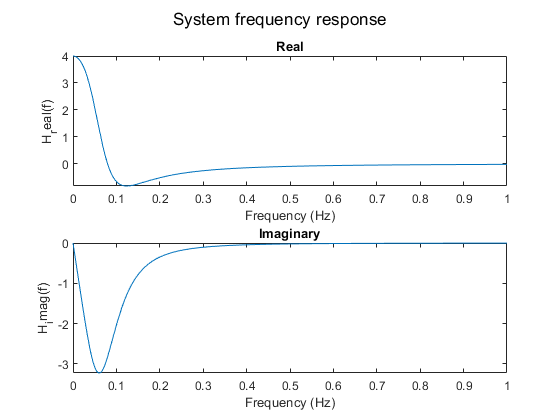

Hreal = @(f) real(((omega_d^2-4*pi^2*f^2+zeta^2*omega_n^2)-4i*pi*f*zeta*omega_n)...
    /((omega_d^2-4*pi^2*f^2+zeta^2*omega_n^2)^2+(4*pi*f*zeta*omega_n)^2));
Himag = @(f) imag(((omega_d^2-4*pi^2*f^2+zeta^2*omega_n^2)-4i*pi*f*zeta*omega_n)...
    /((omega_d^2-4*pi^2*f^2+zeta^2*omega_n^2)^2+(4*pi*f*zeta*omega_n)^2));

Hreal(1/(2*pi));
Himag(1/(2*pi));
atan2(Himag(1/(2*pi)), Hreal(1/(2*pi)));
figure
clf
subplot(2,1,1)
fplot(Hreal, [0 1])
xlabel('Frequency (Hz)')
ylabel('H_real(f)')
title('Real')
subplot(2,1,2)
fplot(Himag, [0 1])
xlabel('Frequency (Hz)')
ylabel('H_imag(f)')
title('Imaginary')
sgtitle('System frequency response')

#### (d)

What is the system's steady-state response? Provide your answer in an analytical form, ensuring that the amplitude, phase, etc are correctly determined.

Since the input is purely a sine wave, the steady state response can be determined from the frequency response where $\omega =1\left\lbrack \frac{\mathrm{rad}}{\mathrm{s}}\right\rbrack$. The real, imaginary, and phase components have already been established in the last section. The amplitude can be determined:


$$\begin{array}{l}
|H\left(f\right)|=\sqrt{H_{\mathrm{real}} {\left(f\right)}^2 +H_{\mathrm{imag}} {\left(f\right)}^2 }\\
=\frac{\sqrt{{\left(\omega_d^2 -4\pi^2 f^2 +\zeta^2 \omega_n^2 \right)}^2 +{\left(-4\pi f\zeta \omega_n \right)}^2 }}{{\left(\omega_d^2 -4\pi^2 f^2 +\zeta^2 \omega_n^2 \right)}^2 +{\left(4\pi f\zeta \omega_n \right)}^2 }\\
\Rightarrow |H\left(f\right)|\approx 0\ldotp 9701
\end{array}$$


sqrt(Himag(1/(2*pi))^2 + Hreal(1/(2*pi))^2);

Now that the amplitude and phase angle are known, the steady-state function can be assembled:


$$\begin{array}{l}
\\
y\left(t\right)=H_{\mathrm{real}} \left(\frac{1}{2\pi }\right)\mathrm{cos}\left(t\right)+H_{\mathrm{imag}} \left(\frac{1}{2\pi }\right)\mathrm{sin}\left(t\right)=\left|H\left(\frac{1}{2\pi }\right)\right|\mathrm{sin}\left(t-\angle H\left(\frac{1}{2\pi }\right)\right)\\
\Rightarrow y\left(t\right)\approx 0\ldotp 9701\;\mathrm{sin}\left(t-2\ldotp 3856\right)
\end{array}$$


Now this is graphically compared to the previous plot of $y\left(t\right)$. While the steady-state solution is initially quite far away from the total numerical solution, they quickly converge, and are very similar after ~15 seconds.

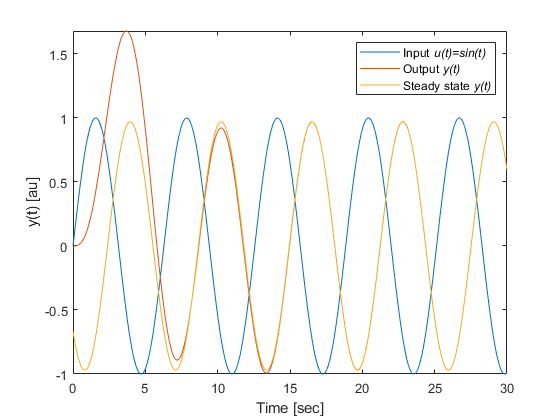

omega_n = 0.5; % Natural frequency, rad/sec
zeta = 1/sqrt(2); % Damping ratio
omega_d = omega_n*sqrt(1-zeta^2); % Damped natural frequency
hFunc = @(t) exp(-zeta*omega_n*t).*sin(omega_d*t)/omega_d;
xFunc = @(t) sin(t);
yFunc = @(t) integral(@(tau) hFunc(tau).*xFunc(t-tau), 0, t);
ySteadyState = @(t) 0.9701*sin(t-2.3856);
figure
clf
fplot(xFunc, [0, 30])
hold on
fplot(yFunc, [0, 30])
fplot(ySteadyState, [0 30])
legend(["Input \it{u(t)=sin(t)}" "Output \it{y(t)}" "Steady state \it{y(t)}"])
xlabel('Time [sec]')
ylabel('y(t) [au]')

#### (e)

How long does the system take to reach the steady state solution? Justify your answer.

Despite the fact that the impuse response oscillates, the amount to which the system has adopted the steady-state equation can, effectively, be defined by the exponential term, since that sets the amplitude of the oscillation. Therefore the same method of integrating the exponential term $h^* \left(t\right)=\zeta \omega_n \mathrm{exp}\left(-\zeta \omega_n t\right)$ in the impulse response can be used:


$$\int_0^{\infty } h^* \left(t\right)\;dt=\int_0^{\infty } \zeta \omega_n \mathrm{exp}\left(-\zeta \omega_n t\right)\;dt=\frac{\zeta \omega_n }{\zeta \omega_n }\left(e^{-\infty } -e^0 \right)=1$$


So a value of 1 indicates that the function has fully reached the steady state. This can be solved for any arbitrary desired percentage. For example, the system has converged 99% of the way to steady state (i.e., 99% of the area under the transfer function is contributing to the output response, and only 1% of the response is due to transient effects) when:


$$\begin{array}{l}
0\ldotp 99=\int_0^T \zeta \omega_n \mathrm{exp}\left(-\zeta \omega_n t\right)\;dt=\frac{-\zeta \omega_n }{\zeta \omega_n }\left(e^{-\zeta \omega_n T} -e^0 \right)=1-e^{-\zeta \omega_n T} \\
\Rightarrow e^{-\zeta \omega_n T} =0\ldotp 01\\
\Rightarrow T=-\frac{1}{\zeta \omega_n }\cdot \mathrm{ln}\left(0\ldotp 01\right)\approx 13\ldotp 03\;\left\lbrack \mathrm{s}\right\rbrack 
\end{array}$$


-1/(zeta*omega_n)*log(0.01);

This matches up with visual inspection of the above graph: after 13 seconds, the steady state and total solutions have nearly completely converged.

## Problem 2 (30 points)

In a recent experiment, you wanted to characterize a new sensor by measuring its response to a short-duration pulse input. (Two examples could be striking a plate with an accelerometer on it or clapping in front of a microphone.)

You know your sensor is capable of responding to high-frequency forcing, but you'd like to determine the maximum bandwidth. Your advisor tells you this is the range of frequencies over which the sensor can be used with high accuracy.

You measured the sensor's output with an oscilloscope and imported the data into Matlab and plotted it. Use these data to estimate the frequency response function and determine its bandwidth.

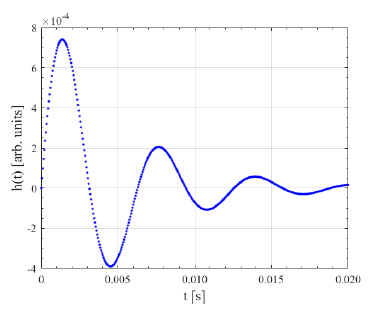

Load the data from the supplied `problem2.mat` file. There should be two variables: `h` (in arbitary units) and `t` (in seconds.)

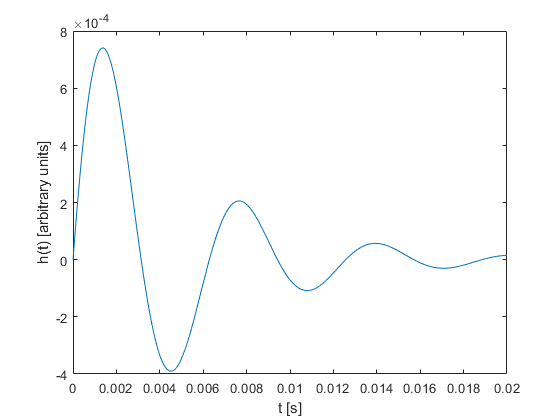

load problem2.mat;
figure
clf
plot(t, h)
xlabel('t [s]')
ylabel('h(t) [arbitrary units]')

### (a)

What order dynamic system do you think best approximates this sensor?

This appears to be a second order under-damped system. This can be determined from the fact that it oscillates. A first-order system would exponentially decay towards a single value (and so would an over-damped second-order system.)

### (b)

Based on your response to (a), what are the relevant characteristic parameters for this system (e.g., time constant, damping ratio, natural frequency, etc.)

HINT: use a few key features from the data. Analyze the general form for the chosen $h\left(t\right)$ function and find an expression for the zero-crossing points. From there you could use guess and check to find other relevant parameters. Do not use curve fitting tools.

First, the damped natural frequency can be found. This is determined by finding the time between the first and third zero crossings (one period.)

times = (t<0.008) & (t>0.004);
timeSection = t(times);
[~, zeroIndex] = min(abs(h(times)));
zeroTime = timeSection(zeroIndex);
omega_d = 1/0.0063*2*pi;

The third zero crossing is at $t\approx 0\ldotp 0063\;\left\lbrack \mathrm{s}\right\rbrack$. Since the first zero crossing is at $t=0\;\left\lbrack \mathrm{s}\right\rbrack$, the period of the damped natural frequency must be equal to $0\ldotp 0063\;\left\lbrack \mathrm{s}\right\rbrack$. The damped natural frequency $f_d \approx \frac{1\;\left\lbrack \mathrm{cycle}\right\rbrack }{0\ldotp 0063\;\left\lbrack \mathrm{s}\right\rbrack }\approx 157\ldotp 7\;\left\lbrack \mathrm{Hz}\right\rbrack \approx 997\;\left\lbrack \frac{\mathrm{rad}}{\mathrm{s}}\right\rbrack \ldotp$

Next, the time constant can be found. This can be done by evaluating the change in amplitude between two adjacent peaks.

peak1Indices = (t<0.004);
timeSection = t(peak1Indices);
[peak1Height, peak1Index] = max(h(peak1Indices));
peak1Height;
peak1Time = timeSection(peak1Index);
peak2Indices = (t>0.004)&(t<0.01);

timeSection = t(peak2Indices);
[peak2Height, peak2Index] = max(h(peak2Indices));
peak2Height;
peak2Time = timeSection(peak2Index);
peakheightRatio = peak2Height/peak1Height;

Over one damped period, the amplitude decreases by ~72%. The time constant can be calculated:


$$\left(0\ldotp 2774\right)=\mathrm{exp}\left(-\frac{0\ldotp 0063\;\left\lbrack \mathrm{s}\right\rbrack }{\tau }\right)\Rightarrow \tau \approx 0\ldotp 0049\;\left\lbrack \mathrm{s}\right\rbrack$$


The ratio between peaks can also be used to estimate the damping ratio:


$$\zeta =\frac{1}{\sqrt{1+{\left(\frac{2\pi }{\mathrm{ln}\left(0\ldotp 2774\right)}\right)}^2 }}\approx 20%$$


zeta = 1./(1+(2*pi/log(0.2774)).^2).^0.5;

Finally, since the damping ratio has been obtained, the undamped natural frequency can also be calculated:


$$\omega_d =\omega_n \sqrt{1-\zeta^2 }\Rightarrow \omega_n =\frac{\omega_d }{\sqrt{1-\zeta^2 }}\approx 1018\;\left\lbrack \frac{\mathrm{rad}}{\mathrm{sec}}\right\rbrack \approx 162\;\left\lbrack \mathrm{Hz}\right\rbrack$$


omega_n=omega_d/sqrt(1-zeta^2);
omega_n/(2*pi);

### (c)

What does the sensor's frequency response function look like? Plot the magnitude and phase as functions of frequency.

(Note: I choose to execute this using the discrete Fourier transform since the first problem already required finding the analytical solution to a frequency response function and graphing it. It would, however, be simple to re-use the real and imaginary functions previously defined with updated $\omega_n ,\omega_d ,\zeta$ values, and adjust them to return the magnitude and phase angle.) 

The frequency response can be plotted by taking the discrete Fourier Transform of the provided signal. Note that the scale of the signal can't be determined, since the magnitude of the input is not known, but this should be proportional to the actual frequency response.

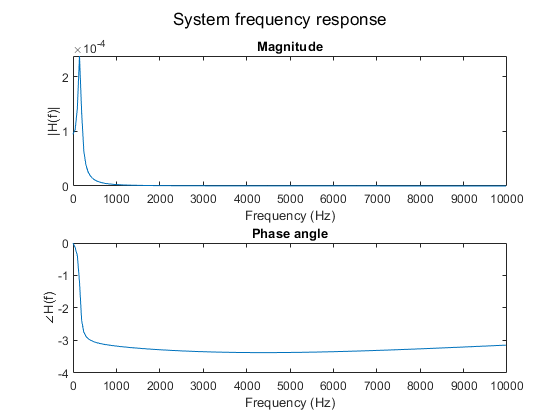

% Perform the FFT
fftVals = fft(h) / (length(h)/2);
fftVals = fftVals(1:length(h)/2+1);

samplingRate = 1/(t(2)-t(1));
freqVec = [0:samplingRate/length(h):(1-1/(2*length(h)))*samplingRate];
freqVec = freqVec(1:length(h)/2+1);

figure
clf
subplot(2,1,1)
plot(freqVec, abs(fftVals))
xlabel('Frequency (Hz)')
ylabel('|H(f)|')
title('Magnitude')
subplot(2,1,2)
plot(freqVec, unwrap(atan2(imag(fftVals), real(fftVals))))

xlabel('Frequency (Hz)')
ylabel('{\angle}H(f)')
title('Phase angle')
sgtitle('System frequency response')

It is odd that the phase of the response appears to curve back at high frequencies. This is atypical behavior for a standard single degree of freedom, second-order linear model. This could be due to measurement error or some other issue. Regardless, the result is minimal: this abberent behavior only occurs at relatively high frequencies where the sensor output is highly attenuated.

### (d)

What does this tell us about the sensor's response characteristics?

The below plot shows a log-log plot of the sensor response, displaying the gain in decibels. It can be seen that the sensor will only have a small region of close-to-linear response. Note that, as before, the magnitude shown is arbitrary, since the magnitude of the input to the sensor is not known (in the case where a plate was struck with a hammer, for example, the force of the hammer impact was not recorded. Technically, it is not possible to record a pure impulse since it has 0 length and infinite magnitude, but since a true impulse is not physically possible, an instrumented hammer with a piezoelectric sensor can be used to measure the input force profile, which can then be converted to the frequency spectrum.)

The natural frequency of the sensor is of relatively small important here: it only provides about 7.5 dB of gain compared to a static signal. The rapid attenuation above the natural frequency is more responsible for the limited bandwidth of the sensor.

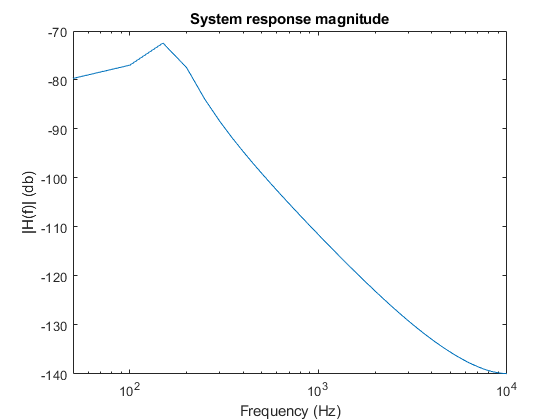

figure
clf
semilogx(freqVec, log10(abs(fftVals))*20)
xlabel('Frequency (Hz)')
ylabel('|H(f)| (db)')
title('System response magnitude')

### (e)

What is the sensor's bandwidth? Provide both upper and lower frequency bounds where the sensor's response is within $\pm 3\;\left\lbrack \textrm{dB}\right\rbrack$ of being flat.

The widest section would be the position shown in the plot below, with the middle gain at the dashed red line. The highest gain value is ~-72.5 dB, and the lowest gain is ~-78.5 dB. This relatively flat region extends from roughly 68 Hz to 206 Hz, and includes the peak of the sensor's natural frequency.

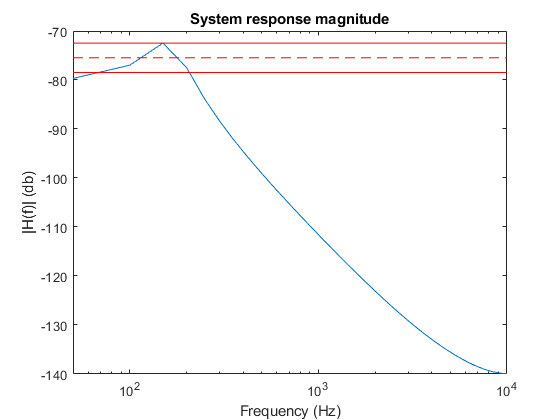

highestDb = max(log10(abs(fftVals))*20);
lowestDb = highestDb-6;
figure
clf
semilogx(freqVec, log10(abs(fftVals))*20)
xlabel('Frequency (Hz)')
ylabel('|H(f)| (db)')
title('System response magnitude')
hold on
semilogx([freqVec(2) max(freqVec)], [highestDb highestDb], 'Color', 'red')
semilogx([freqVec(2) max(freqVec)], [highestDb highestDb]-3, '--', 'Color', 'red')
semilogx([freqVec(2) max(freqVec)], [lowestDb lowestDb], 'Color', 'red')

## Problem 3 (25 points)

The frequency response function for a linear system is shown below. Load the data from `problem3.mat`. There are three variables: `mag` (in dB), `phase` (in degrees), and `freq` (in Hz.)

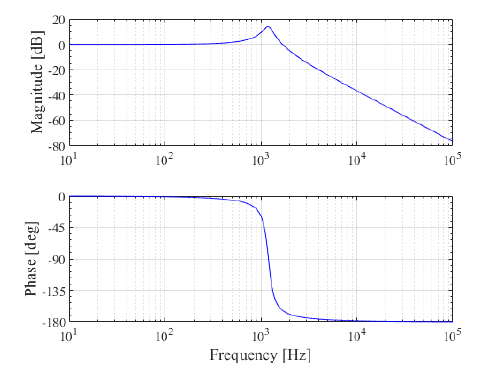

load problem3.mat

### (a)

What is the order of this system?

This is a second order system. This can be seen because there is a clear peak in the magnitude at a non-zero frequency, while a first-order system has the highest response to static (i.e., zero-frequency) loads. While it is not specified in the problem, this system will be treated as a spring-mass-damper system, since I work with those a lot in my research, and am thus more familiar with the terminology than finding an equivelent electronic or other system.

### (b)

What are the relevant characteristic parameters for this system?

First, for convenience the values are converted from the logarithmic magnitude/phase plot to a linear real/imaginary plane. The frequency axis is only shown from 0 to 5000 Hz, since that is where the peak is.

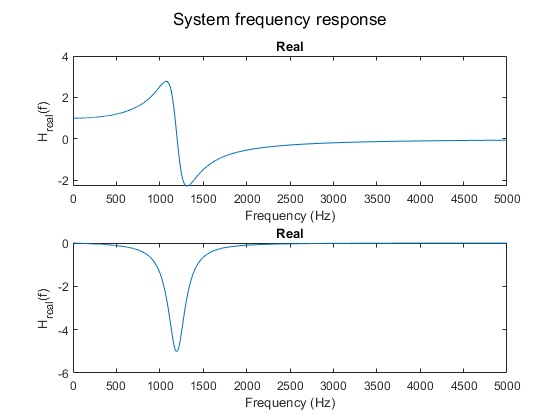

absMag = 10.^(mag./20);
complexVals = absMag .* exp(1i*phase/180*pi);
figure
clf
subplot(2,1,1)
plot(freq, real(complexVals))
xlim([0 5e3])
title('Real')
xlabel('Frequency (Hz)')
ylabel('H_{real}(f)')
subplot(2,1,2)
plot(freq, imag(complexVals))
xlim([0 5e3])
title('Real')
xlabel('Frequency (Hz)')
ylabel('H_{real}(f)')
sgtitle('System frequency response')

The modal parameters for this system will be identified using a peak-picking method. The natural frequency $f_n$ can be found as the frequency where the imaginary component of the FRF has the highest magnitude. From the above graph, $\omega_n \approx 1194\;\left\lbrack \mathrm{Hz}\right\rbrack \approx 7502\;\left\lbrack \frac{\mathrm{rad}}{\mathrm{sec}}\right\rbrack$ 

[~, naturalFreqIndex] = max(abs(imag(complexVals)));
omega_n = freq(naturalFreqIndex)*2*pi;

The damping ratio can be found by looking at the distance between the maximum and minimum values of the real component of the FRF, using the formula $\zeta =\frac{f_{\mathrm{min}\;\mathrm{real}} -f_{\mathrm{max}\;\mathrm{real}} }{f_n }$. The minimum value is found at ~1314 Hz, and the maximum value is found at 1073 Hz. Therefore, the damping ratio is:


$$\zeta =\frac{1314\;\left\lbrack \mathrm{Hz}\right\rbrack -1073\;\left\lbrack \mathrm{Hz}\right\rbrack }{1194\;\left\lbrack \mathrm{Hz}\right\rbrack }\approx 0\ldotp 202$$


[~, minFreqIndex] = min(real(complexVals));
[~, maxFreqIndex] = max(real(complexVals));
minFreq = freq(minFreqIndex);
maxFreq = freq(maxFreqIndex);
zeta = abs(maxFreq - minFreq)./naturalFrequency;

The damped natural frequency can be calculated from $\zeta ,\omega_n$:


$$\omega_d =\omega_n \sqrt{1-\zeta^2 }\approx 1170\;\left\lbrack \mathrm{Hz}\right\rbrack \approx 7350\;\left\lbrack \frac{\mathrm{rad}}{\mathrm{sec}}\right\rbrack$$


omega_d=omega_n*sqrt(1-zeta^2);

The modal parameters stiffness, mass, and damping coefficients can also be determined. They aren't necessary to solve this problem, but may be useful for other analysis. The stiffness can be determined based on the formula $k={\left(2A\zeta \right)}^{-1}$, where $A$ is the magnitude of the peak of the imaginary component.


$$\begin{array}{l}
A\approx 5\ldotp 025\\
\Rightarrow k={\left(2\cdot 5\ldotp 025\cdot 0\ldotp 2018\right)}^{-1} \approx 0\ldotp 493
\end{array}$$


peakAmplitude = max(abs(complexVals));
stiffness = (2*peakAmplitude * zeta).^-1;

Now the mass can be determined:


$$\omega_n =\sqrt{\frac{k}{m}}\Rightarrow m=\frac{k}{\omega_n^2 }\approx 8\ldotp 76\cdot {10}^{-9}$$


mass = stiffness/(naturalFrequency * 2 * pi).^2;

Finally, the critical and actual damping coefficients can be found:

criticalDampingCoefficient = 2*sqrt(mass*stiffness)

criticalDampingCoefficient = 1.3140e-04

actualDampingCoefficient = criticalDampingCoefficient*zeta

actualDampingCoefficient = 2.6519e-05

### (c)

What is the system's transfer function? Express it analytically, and simplify the fraction.

This system is underdamped ($\zeta <1$). The transfer function equation for an underdamped second order system was derived in problem 1, part 2, sections c and d. The full proof can be seen there, but the results are:


$$\begin{array}{l}
H\left(f\right)=\frac{\omega_d^2 -4\pi^2 f^2 +\zeta^2 \omega_n^2 -4j\pi f\zeta \omega_n }{{\left(\omega_d^2 -4\pi^2 f^2 +\zeta^2 \omega_n^2 \right)}^2 +{\left(4\pi f\zeta \omega_n \right)}^2 }\\
H_{\mathrm{real}} \left(f\right)=\frac{\omega_d^2 -4\pi^2 f^2 +\zeta^2 \omega_n^2 }{{\left(\omega_d^2 -4\pi^2 f^2 +\zeta^2 \omega_n^2 \right)}^2 +{\left(4\pi f\zeta \omega_n \right)}^2 },H_{\mathrm{imag}} \left(f\right)=\frac{-4\pi f\zeta \omega_n }{{\left(\omega_d^2 -4\pi^2 f^2 +\zeta^2 \omega_n^2 \right)}^2 +{\left(4\pi f\zeta \omega_n \right)}^2 }
\end{array}$$



$$\begin{array}{l}
\left|H\left(f\right)\right|=\sqrt{H_{\mathrm{real}} {\left(f\right)}^2 +H_{\mathrm{imag}} {\left(f\right)}^2 }\\
=\frac{\sqrt{{\left(\omega_d^2 -4\pi^2 f^2 +\zeta^2 \omega_n^2 \right)}^2 +{\left(-4\pi f\zeta \omega_n \right)}^2 }}{{\left(\omega_d^2 -4\pi^2 f^2 +\zeta^2 \omega_n^2 \right)}^2 +{\left(4\pi f\zeta \omega_n \right)}^2 }\\
\angle H\left(f\right)=\mathrm{atan2}\left(H_{\mathrm{imag}} \left(f\right),H_{\mathrm{real}} \left(f\right)\right)
\end{array}$$


Where:


$$\begin{array}{l}
\omega_n \approx 7502\;\left\lbrack \frac{\mathrm{rad}}{\mathrm{sec}}\right\rbrack \\
\zeta \approx 0\ldotp 202\\
\omega_d \approx 7350\;\left\lbrack \frac{\mathrm{rad}}{\mathrm{sec}}\right\rbrack 
\end{array}$$


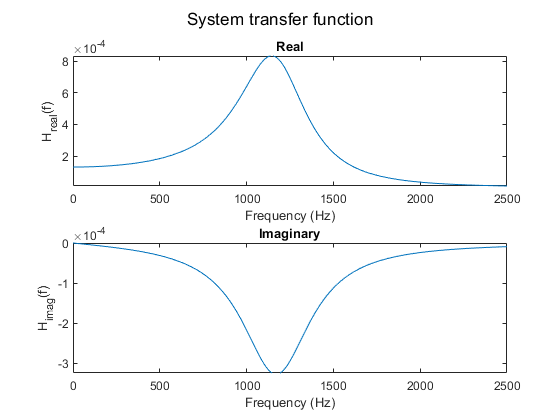

Hreal = @(f) real(((omega_d^2-4*pi^2*f^2+zeta^2*omega_n^2)-4i*pi*f*zeta*omega_n)...
    /((omega_d^2-4*pi^2*f^2+zeta^2*omega_n^2)^2+(4*pi*f*zeta*omega_n)^2));
Himag = @(f) imag(((omega_d^2-4*pi^2*f^2+zeta^2*omega_n^2)-4i*pi*f*zeta*omega_n)...
    /((omega_d^2-4*pi^2*f^2+zeta^2*omega_n^2)^2+(4*pi*f*zeta*omega_n)^2));

figure
clf
subplot(2,1,1)
fplot(@(f) real(Hfunc(f)), [0 2500])
xlabel('Frequency (Hz)')
ylabel('H_{real}(f)')
title('Real')
subplot(2,1,2)
fplot(@(f) imag(Hfunc(f)), [0 2500])
xlabel('Frequency (Hz)')
ylabel('H_{imag}(f)')
title('Imaginary')
sgtitle('System transfer function')

### (d)

What are the system's poles and/or zeros?

Given the transfer function:


$$H\left(f\right)=\frac{\omega_d^2 -4\pi^2 f^2 +\zeta^2 \omega_n^2 -4j\pi f\zeta \omega_n }{{\left(\omega_d^2 -4\pi^2 f^2 +\zeta^2 \omega_n^2 \right)}^2 +{\left(4\pi f\zeta \omega_n \right)}^2 }$$


The poles will occur when the bottom of the equation ${\left(\omega_d^2 -4\pi^2 f^2 +\zeta^2 \omega_n^2 \right)}^2 +{\left(4\pi f\zeta \omega_n \right)}^2$ goes to zero, while the zeros will occur when the top $\omega_d^2 -4\pi^2 f^2 +\zeta^2 \omega_n^2 -4j\pi f\zeta \omega_n$ goes to zero. First the zeros will be solved for:


$$0=\omega_d^2 -4\pi^2 f^2 +\zeta^2 \omega_n^2 -4j\pi f\zeta \omega_n$$


This is difficult to solve in the general case, so the specific values for each parameter will be plugged in:


$$\begin{array}{l}
\omega_n \approx 7502\;\left\lbrack \frac{\mathrm{rad}}{\mathrm{sec}}\right\rbrack \\
\zeta \approx 0\ldotp 202\\
\omega_d \approx 7350\;\left\lbrack \frac{\mathrm{rad}}{\mathrm{sec}}\right\rbrack 
\end{array}$$



$$\begin{array}{l}
\Rightarrow 0\approx {7350}^2 -4\pi^2 f^2 +0\ldotp {202}^2 \cdot {7502}^2 -4j\pi f\cdot 0\ldotp 202\cdot 7502\approx -39\ldotp 4784f^2 -j\;19043\ldotp 1f+5\ldotp 632{\cdot 10}^7 \\
\Rightarrow f^2 +j\;482\ldotp 368\;f-1\ldotp 427\cdot {10}^6 \approx 0
\end{array}$$


This equation can be solved using the quadratic formula:


$$\begin{array}{l}
f=\frac{-482\ldotp 368\;j\pm \sqrt{-{\left(482\ldotp 368\right)}^2 +4\cdot 1\ldotp 427\cdot {10}^6 }}{2}\\
\Rightarrow f\approx \pm 1170-241j\;\left\lbrack \mathrm{Hz}\right\rbrack 
\end{array}$$


This gives the zeros, which occur when $f\approx 1170-241j\;\left\lbrack \mathrm{Hz}\right\rbrack ,-1170-241j\;\left\lbrack \mathrm{Hz}\right\rbrack$.

Now the poles are found. Again, the specific values will be plugged into the quadratic equation:


$$\begin{array}{l}
{0\approx \left({7350}^2 -4\pi^2 f^2 +{0\ldotp 202}^2 \cdot {7502}^2 \right)}^2 +{\left(4\pi f\cdot 0\ldotp 202\cdot 7502\right)}^2 \\
\approx 1558\ldotp 55f^4 -4\ldotp 084\cdot {10}^9 f^2 +3\ldotp 172\cdot {10}^{15} 
\end{array}$$


$f^2$ can now be solved using the quadratic formula:


$$\begin{array}{l}
f^2 =\frac{4\ldotp 084\cdot {10}^9 \pm \sqrt{{\left(-4\ldotp 084\cdot {10}^9 \right)}^2 -4\cdot 1558\ldotp 55\cdot 3\ldotp 172\cdot {10}^{15} }}{2\cdot 1558\ldotp 55}\\
\Rightarrow f^2 \approx 1\ldotp 31\cdot {10}^6 \pm 564300j\\
\Rightarrow f^2 -1\ldotp 31\cdot {10}^6 \mp 564300j\approx 0
\end{array}$$


This can, again, be solved for using the quadratic formula for both cases:


$$f=\frac{0\pm \sqrt{0-4\cdot \left(-1\ldotp 31\cdot {10}^6 -564300j\right)}}{2},\frac{0\pm \sqrt{0-4\cdot \left(-1\ldotp 31\cdot {10}^6 +564300j\right)}}{2}$$


After evaluating all four possible cases, $f\approx \pm 1170\pm 241\;\left\lbrack \mathrm{Hz}\right\rbrack$. This overlaps with the zeros that were previously identified. Those two points will have both the top and bottom go towards 0, and will have more complex behavior that is beyond the scope of this assignment to analyze.

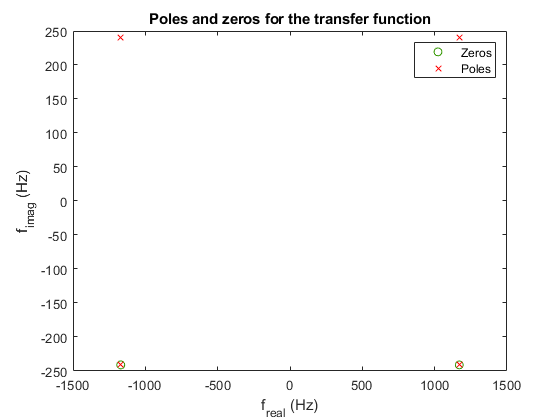

poles = [1170 241; 1170 -241; -1170 241; -1170 -241];
zeros = [1170 -241; -1170 -241];
figure
clf
plot(zeros(:,1), zeros(:,2), 'o', 'color', [50 150 0]/255)
hold on
plot(poles(:,1), poles(:,2), 'x', 'color', 'red')
legend(["Zeros" "Poles"])
xlabel('f_{real} (Hz)')
ylabel('f_{imag} (Hz)')
title('Poles and zeros for the transfer function')

### (e)

Does this system ever have an amplified output? If so, where is it amplified (provide upper and lower frequency bounds)? What is the maximum amplification in gain factor (using $\textrm{Mag}\;\left\lbrack \textrm{dB}\right\rbrack =20\;\log_{10} \left(\textrm{Gain}\right)$?

The output is amplified at any frequency where the amplitude of the FRF is above 1 (alternatively, where the gain factor is above 0.) This occurs from $0\;\left\lbrack \mathrm{Hz}\right\rbrack <f\le 1680\;\left\lbrack \mathrm{Hz}\right\rbrack$. The maximum gain factor can be found directly from the magnitude plot, and is equal to $|H\left(1194\;\left\lbrack \mathrm{Hz}\right\rbrack \right)|\approx 14\ldotp 02\;\left\lbrack \mathrm{dB}\right\rbrack$.

maxAmplification = max(mag)

maxAmplification = 14.0230

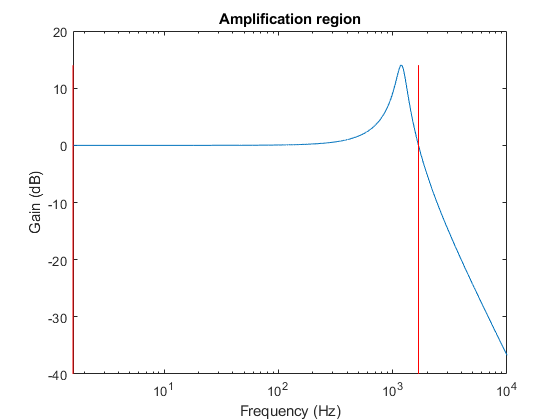

amplifiedFrequencies = freq(mag > 0);
minAmplifiedFreq = min(amplifiedFrequencies);
maxAmplifiedFreq = max(amplifiedFrequencies);
figure
clf
semilogx(freq, mag)
xlim([0 10000])
hold on
axis('manual')
semilogx([minAmplifiedFreq minAmplifiedFreq], [min(mag) max(mag)], 'Color', 'red')
semilogx([maxAmplifiedFreq maxAmplifiedFreq], [min(mag) max(mag)], 'Color', 'red')
title('Amplification region')
xlabel('Frequency (Hz)')
ylabel('Gain (dB)')

### (f)

Does this system ever have an attenuated output? If so, where is it attenuated (provide upper and lower frequency bounds)? What is the attenuation rate, in both dB/decade and dB/octave?

The system will have attenuated output anywhere where the magnitude in decibels is less than 0. This occurs at any frequency above the amplification upper bound of 1680 Hz, see the previous figure.

The attenuation rate can be calculated from the ratio of the previously defined gain magnitude $\left|H\left(f\right)\right|$, after converting to decibels:


$$\begin{array}{l}
\frac{\mathrm{Rate}}{\mathrm{decade}}=20\cdot {\mathrm{log}}_{10} \left|H\left(f\right)\right|-20\cdot {\mathrm{log}}_{10} \left|H\left(10f\right)\right.\\
\frac{\mathrm{Rate}}{\mathrm{octave}}=20\cdot {\mathrm{log}}_{10} \left|H\left(f\right)\right|-20\cdot {\mathrm{log}}_{10} \left|H\left(8f\right)\right.
\end{array}$$


This is evaluated numerically using the base frequency of 10000 Hz, since that is well ito the attenuation region:


$$\begin{array}{l}
\frac{\mathrm{Rate}}{\mathrm{decade}}\approx 40\\
\frac{\mathrm{Rate}}{\mathrm{octave}}\approx 36
\end{array}$$


HMag = @(f)sqrt(Hreal(f)^2+Himag(f)^2);
ratePerDecade = 20*log10(HMag(10000))-20*log10(HMag(10000*10));
ratePerOctave = 20*log10(HMag(10000))-20*log10(HMag(10000*8));

## Problem 4 (15 points)

Provide explanations, graphs, and analytical work for the following questions:

### (a)

A thermometer, initially at 20 degrees C, is suddenly immersed in a tank of water with a temperature of 80 degrees C. If the time constant of the thermometer is 2 seconds, what temperature will the thermometer read after 5 seconds?

This can be defined as a first-order system where:


$$y\left(t\right)=a\;\mathrm{exp}\left(-\frac{t}{\tau }\right)+b$$


The various coefficients can be solved from the givens and initial conditions. Since the tank of water is at 80 degrees C, the thermometer will eventually approach that temperature as $t\to \infty$ (assuming that the tank temperature is constant and has sufficiently large thermal mass relative to the thermometer that changes from the thermometer can be ignored):


$$\begin{array}{l}
\underset{t\to \infty }{\mathrm{lim}} y\left(t\right)=80=a\;\mathrm{exp}\left(-\frac{\infty }{\tau }\right)+b\\
\Rightarrow b=80
\end{array}$$


a can be calculated based on the initial condition $t=0$:


$$\begin{array}{l}
y\left(0\right)=20=a\;\mathrm{exp}\left(-\frac{0}{\tau }\right)+80=a+80\\
\Rightarrow a=-60
\end{array}$$


The time constant $\tau$ is given. Therefore, the time-respones of the thermometer can be written:


$$\begin{array}{l}
y\left(t\right)=80-60\;\mathrm{exp}\left(-\frac{t}{2}\right)\\
y\left(5\right)=80-60\;\mathrm{exp}\left(-\frac{5}{2}\right)\approx 75\ldotp 1\;\left\lbrack \mathrm{°C}\right\rbrack 
\end{array}$$


This can be plotted:

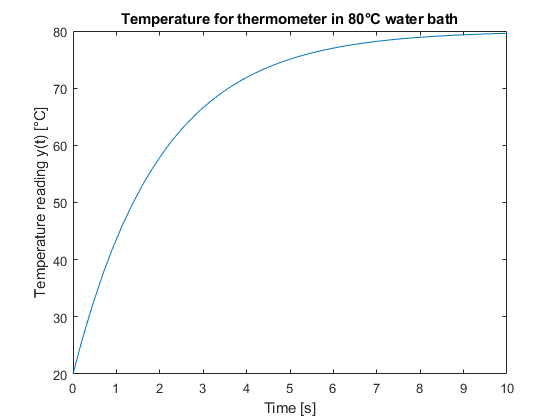

temp=@(t)80-60*exp(-t/2);
figure
clf
fplot(temp, [0 10]);
xlabel('Time [s]')
ylabel('Temperature reading y(t) [°C]')
title('Temperature for thermometer in 80°C water bath')

### (b)

A signal amplifier is set to a gain of 60 dB. If the voltage input to the amplifer is 3 mV, what is the output voltage that would be measured?

The gain in decibels is equal to $20\cdot {\mathrm{log}}_{10} \left(|H\left(f\right)|\right)=20\cdot {\mathrm{log}}_{10} \left(\frac{V_{\mathrm{out}} }{V_{\mathrm{in}} }\right)$. For this case:


$$\begin{array}{l}
60\;=20\cdot {\mathrm{log}}_{10} \left(\frac{V_{\mathrm{out}} }{3\;\left\lbrack \mathrm{mV}\right\rbrack }\right)\\
\Rightarrow 3={\mathrm{log}}_{10} \left(\frac{V_{\mathrm{out}} }{3\;\left\lbrack \mathrm{mV}\right\rbrack }\right)\\
\Rightarrow {10}^3 =1000=\frac{V_{\mathrm{out}} }{3\left\lbrack \mathrm{mV}\right\rbrack }\\
\Rightarrow V_{\mathrm{out}} =3000\;\left\lbrack \mathrm{mV}\right\rbrack =3\left\lbrack V\right\rbrack 
\end{array}$$


### (c)

Consider the first-order system specified in problem 1. What is the steady-state response of this system to a unit ramp input, $u\left(t\right)=t$?

The impulse response function of this first-order system is $h\left(t\right)=\frac{1}{T}e^{\frac{-t}{T}}$ where the time constant $T=2\;\left\lbrack \mathrm{s}\right\rbrack$, and the input function is a unit ramp $u\left(t\right)=t$. The time response can be determined by integrating the product:


$$y\left(t\right)=\int_0^t h\left(\tau \right)u\left(t-\tau \right)\;d\tau =\frac{1}{T}\int_0^t \left(t-\tau \right)\mathrm{exp}\left(-\frac{\tau }{T}\right)\;d\tau$$


This integral can be computed using integration by parts: $\int u\;v\;dx=u\int v\;dx-\int u^{\prime } \left(\int v\;\mathrm{dx}\right)$. Here, $x=\tau ,\;u=u\left(t-\tau \right)=t-\tau ,v=h\left(\tau \right)=\mathrm{exp}\left(-\frac{\tau }{T}\right)$. Since a definite integral is being computed, the constants of integration are ignored. Therefore:


$$\begin{array}{l}
u^{\prime } =\frac{d}{d\tau }\left(t-\tau \right)=-1\\
\int v\;dx=\int \mathrm{exp}\left(-\frac{\tau }{T}\right)\;d\tau =-T\;\mathrm{exp}\left(-\frac{\tau }{T}\right)\\
\Rightarrow \frac{1}{T}\int h\left(\tau \right)u\left(t-\tau \right)\;d\tau =\frac{1}{T}\left(\left(t-\tau \right)\left(-T\;\mathrm{exp}\left(-\frac{\tau }{T}\right)\right)-\int -1\cdot \left(-T\;\mathrm{exp}\left(-\frac{\tau }{T}\right)\right)\;d\tau \right)\\
=\left(t-\tau \right)\left(-\;\mathrm{exp}\left(-\frac{\tau }{T}\right)\right)-\int \left(\;\mathrm{exp}\left(-\frac{\tau }{T}\right)\right)\;d\tau \\
=\left(t-\tau \right)\left(-\;\mathrm{exp}\left(-\frac{\tau }{T}\right)\right)+T\mathrm{exp}\left(-\frac{\tau }{T}\right)\\
\Rightarrow y\left(t\right)=\left(\left(t-t\right)\left(-\;\mathrm{exp}\left(-\frac{t}{T}\right)\right)+T\;\mathrm{exp}\left(-\frac{t}{T}\right)\right)-\left(\left(t-0\right)\left(-\;\mathrm{exp}\left(-\frac{0}{T}\right)\right)+T\;\mathrm{exp}\left(-\frac{0}{T}\right)\right)\\
=\left(T\;\mathrm{exp}\left(-\frac{t}{T}\right)\right)+t-T
\end{array}$$


As time progresses, this trends towards a linear response lagging behind the input as the exponential term decays towards zero. Therefore:


$$\lim_{t\to \infty } y\left(t\right)=t-T$$


This result is confirmed in the plot below, comparing the input $u\left(t\right)$ to the analytical and numerical solutions for $y\left(t\right)$.

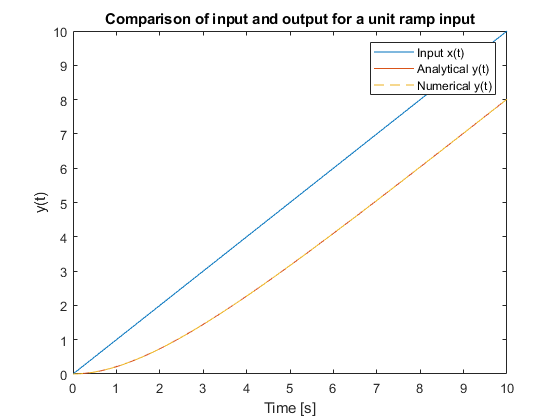

tau=2;
hFunc = @(t) 1/tau .* exp(-t/tau);
xFunc = @(t) t;
yFunc = @(t) integral(@(tau) hFunc(tau).*xFunc(t-tau), 0, t);
yAnalytical=@(t) tau*exp(-t/tau)+t-tau;
figure
clf
fplot(xFunc, [0 10])
hold on
fplot(yAnalytical, [0 10])
fplot(yFunc, [0 10], '--')
legend(["Input x(t)" "Analytical y(t)" "Numerical y(t)"])
xlabel('Time [s]')
ylabel('y(t)')
title('Comparison of input and output for a unit ramp input')

### (d)

Your advisor asked you to characterize a microphone using an acoustic plane wave tube. You recorded the microphone output when the plane wave tube was forced with a single frequency sinusoidal input tone set to 5 kHz. You computer and plotted the power spectrum shown below. Do you think the microphone is behaving linearly for this case? Why or why not? Explain.

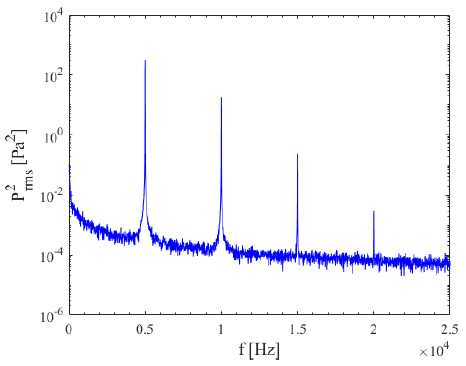

The microphone is behaving non-linearly. A linear system cannot transform the frequency of the input, only change the magnitude and phase of the response. This this sort of harmonic response (at integer multiples of the 5 kHz input frequency) can be seen in linear systems when the input signal is not solely sinusoidal. For example, the below figure from my research shows the Fourier transform of the displacement of a flexure-mounted workpiece as an endmill takes a cut on it. For a stable cut, the cutting forces from the endmill and the displacement are both periodic, repeating once every revolution. While the flexure can be satisfactorily modeled as a linear system for this application, the cutting forces from the endmill are not a pure sinusoid. Therefore, the displacement response of the flexure displays frequency content both at the flute passing frequency ($\frac{3873}{60}\approx 64\ldotp 6\;\left\lbrack \mathrm{Hz}\right\rbrack$ for this example) and at its integer harmonics, shown with the blue lines and circles.

For this problem, however, it was specified that the input frequency is purely sinusoidal. Therefore, it can be concluded that the microphone is exhibiting non-linear behavior.